# DoE Generator Live Script

## Create structure listing identification parameters

The Fouling Model Simulation Code is supplied with 3 structures which configure the model for each simulation run:

- ***BoundCond***: supplies the boundary conditions for the simulation.

- ***ModelPara***: defines the identification parameter settings for the current simulation.

- ***Options***: enables or disables the soot deposit and removal mechanisms and the HC and water condensation and evaporiasation models.

Note, distributed parameters are represented as B-splines for compactness and are automatically converted to lookup tables by the code. By convention, it is assumed the lookup contains the axial distance data in the first row! This convention ensures consistency.

clear;
clc;

F(1).Name = "soot_phi0";
F(1).Units = "[m]";
F(1).Fixed = false;                 % Distributed parameter
F(1).Lo = 0.00001;
F(1).Hi = 0.0005;
F(1).Sz = [2, 21];
F(1).Type = "Boundary";
F(2).Name = "k_d";                  % Deposit thermal conductivity
F(2).Units = "[W/m/K]";
F(2).Fixed = false;                 % Distributed parameter
F(2).Lo = 0.02;   
F(2).Hi = 0.25;
F(2).Sz = [2, 11];
F(2).Type = "Parameter";
F(3).Name = "rho_d";                % Deposit density
F(3).Units = "[kg/m^3]";
F(3).Fixed = false;                 % Distributed parameter
F(3).Lo = 5;
F(3).Hi = 60;
F(3).Sz = [2, 11];
F(3).Type = "Parameter";
F(4).Name = "K";                    % Shear stress removal mechanism gain
F(4).Units = "";
F(4).Fixed = true;                  % Fixed parameter
F(4).Lo = 0.01;
F(4).Hi = 0.3;
F(4).Sz = [1,1]; 
F(4).Type = "Parameter";
% F(4).Name = "Ks";                   % Particle sticking probability gain
% F(4).Units = "";
% F(4).Fixed = true;                  % Fixed parameter
% F(4).Lo = 0.100;
% F(4).Hi = 0.900;
% F(4).Sz = [1,1];                    % Size must be [1,1] for scalar parameter
% F(4).Type = "Parameter";
% F(6).Name = "fRegMP";               % Friction factor regression parameters
% F(6).Units = "[]";
% F(6).Fixed = true;                  % Fixed parameter
% F(6).Lo = [ 0 -0.5; 0.001 -0.3; 0.1 -0.1 ];
% F(6).Hi = [ 0.25 -0.01; 0.1 -0.01; 150 0.1];
% F(6).Sz = [3,2];
% F(6).Type = "Parameter";
% F(4).Name = "K_HCs";                % HC condensation/evaporation gain
% F(4).Units = "";
% F(4).Fixed = true;                  % Fixed parameter
% F(4).Lo = 0.00001;
% F(4).Hi = 0.0050;
% F(4).Sz = [1,1]; 
% F(4).Type = "Parameter";
% F(4).Name = "NuRegMP";              % Nusselt number regression parameters
% F(4).Units = "";
% F(4).Fixed = true;                  % Fixed parameter
% F(4).Lo = 0.0001;
% F(4).Hi = 1;
% F(4).Sz = [1,3]; 
% F(4).Type = "Parameter";

## Enable/Disable Derivative B-Spline Constraints

***Con*** is a multi-dimensional structure specifiying the necessary constraints. The structure must have the fields:

Name              -->  parameter or boundary condition name

derivative        --> set to 0,1 or 2 {0} to specify the spline derivative to which the constraint applies.

type                --> set to '==','>=' or '<='

value             --> constraint bound value

x                    --> Axial coordinates at which constraints apply. Leave empty to specify all training x-ordinates

For example, imagine we require to constrain the second derivative of the initial deposit layer thickness (soot_phi0) to be greater or equal to zero everywhere. Then set:

Con(1).name = 'soot_phi0';

Con(1).derivative = 2;

Con(1).type = '>=';

Con(1).value = 0;

Con(1).x = [];

ConstraintsEnable = true;
if ConstraintsEnable
    % Constrain the second derivative of the initial deposit layer thickness >= 0
    Con(1).name = 'soot_phi0';                                                          %#ok<*UNRCH> 
    Con(1).derivative = 2;
    Con(1).type = '>=';
    Con(1).value = 0;
    Con(1).x = [];
else
    % disable constraints - do not edit this!!!!!
    Con = struct.empty;
end

## Create Sobol Sequence object and generate experiment

Sobj = SobolSequence( F, Con, "M", 3, "K", 1 );                   % Quadratic B-spline with 1 knots for distributed parameters
%-----------------------------------------------------------------
% Design size is user selectable and sequence should be scrambled.
%-----------------------------------------------------------------
DesignSize = 301;
Sobj = Sobj.generate( DesignSize, "Scramble", true );

## Generate the DoEhook object connecting the BO and ECOMO model objects

H = DoEhook();
H = H.addDesignAvailableListener( Sobj );   % Add listener for the design available event
Sobj.export();                              % Generate the parameter table

## Generate the ECOMO interface object & run the experiment. Create the Bayesian optimisation object at the end of the simulation runs.

E = ecomoInterface();
%-----------------------------------------------------------------------
% Define name of variable to load
%-----------------------------------------------------------------------
StructName = "EGRVars";
E = E.loadIdentificationData( "", StructName );
E = E.addRunExperimentListener( H );
tic;
H.runSimulation();

-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object !
-----run----
new object------ simulate from a new object

toc;

Elapsed time is 577.664271 seconds.


## Generate diagnostic plots

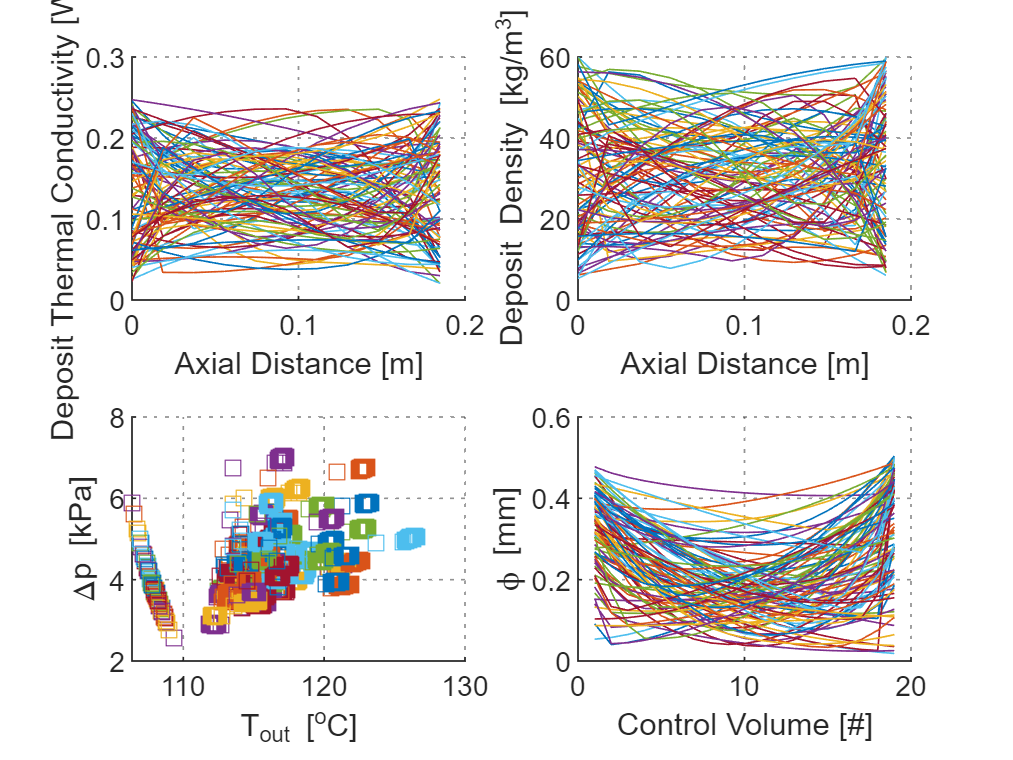

N = Sobj.NumPoints;
figure;
for Q = 1:4
    Ax( Q ) = subplot(2,2,Q);  %#ok<*SAGROW> 
    Ax( Q ).NextPlot = "add";
    grid on;
    Ax( Q ).GridAlpha = 0.5;
    Ax( Q ).GridLineStyle = ":";
end
for Q = 1:N
    plot( Ax( 1 ), E.FM(Q).ModelPara.k_d(:,1), E.FM(Q).ModelPara.k_d(:,2), '-' );     % Thermal conductivity
    plot( Ax( 2 ), E.FM(Q).ModelPara.rho_d(:,1), E.FM(Q).ModelPara.rho_d(:,2), '-');  % Deposit density
    plot( Ax( 3 ), E.FM(Q).T_out_L_degC, E.FM(Q).deltaPre_L_kPa, 's' );               % Temperature out versus delta pressure
    plot( Ax( 4 ), 1000 * E.FM( Q ).phi_soot_tn1, '-' );                              % Deposit thickness
end
xlabel( Ax( 1 ), "Axial Distance [m]");
ylabel( Ax( 1 ), "Deposit Thermal Conductivity [W/K/m]");
xlabel( Ax( 2 ), "Axial Distance [m]");
ylabel( Ax( 2 ), "Deposit Density [kg/m^3]");
xlabel( Ax( 3 ), "T_{out} [^oC]");
ylabel( Ax( 3 ), "\Deltap [kPa]")
xlabel( Ax( 4 ), "Control Volume [#]");
ylabel( Ax( 4 ), "\phi [mm]");

## Minimise the BO Acquisition Function & Update the Training Data

DataBudget = 20;
ConvCounterLimit = 2;
if ( H.Uh == 0 )
    H = H.addProcessNewQueryListener( E );      % Add the necessary listener
end
tic;
if isempty( E.B.Xnext )
    Xlast = E.B.Xbest;
end
Q = 0;
ConvFlg = false;
ConvCounter = 0;

while ( ~ConvFlg )
    Q = Q + 1;                              % data budget counter
    E = E.genNewQuery();                    % Solve the Bayesian optimisation acquisition function
    E.exportNewQuery();                     % Update the training data
    ConvCriteria = abs( ( E.B.Xnext - Xlast )./Xlast );
    if ( Q >= DataBudget )
        ConvFlg = true;
    elseif all( ConvCriteria < 0.00001 ) && ( ConvCounter >= ConvCounterLimit )
        ConvFlg = true;
    elseif all( ConvCriteria < 0.00001 )
        ConvCounter = ConvCounter + 1;
    end
    Xlast = E.B.Xnext;
end

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    6.559683e+02    0.000e+00    8.438e+04
    1      34    5.934293e+02    6.673e-04    1.248e+05    1.060e-01
    2      53    5.924822e+02    6.613e-04    1.253e+05    8.486e-03
    3      71    5.916589e+02    7.407e-04    1.150e+05    7.197e-02
    4      89    5.897597e+02    7.812e-04    1.045e+05    5.061e-01
    5     106    5.781863e+02    1.175e-03    2.415e+05    1.965e-01
    6     125    5.677848e+02    1.028e-03    2.102e+05    3.934e-01
    7     144    5.677487e+02    7.449e-04    3.119e+05    3.317e-01
    8     161    5.610716e+02    8.150e-04    3.690e+05    4.657e-01
    9     178    5.518873e+02    6.179e-04    6.961e+05    5.053e+00
   10     195    5.222717e+02    2.965e-04    7.313e+05    5.736e-01
   11    

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.702531e+02    0.000e+00    7.315e+05
    1      42    4.693108e+02    0.000e+00    7.348e+05    1.309e-03
    2      59    4.571268e+02    0.000e+00    7.244e+05    5.202e+01
    3      78    4.571336e+02    0.000e+00    7.218e+05    2.317e+00
    4      96    4.567466e+02    0.000e+00    7.235e+05    1.284e+00
    5     116    4.565977e+02    0.000e+00    7.211e+05    7.438e-02
    6     134    4.564928e+02    0.000e+00    7.176e+05    4.404e-01
    7     152    4.564863e+02    0.000e+00    7.156e+05    1.605e-01
    8     170    4.564913e+02    0.000e+00    7.144e+05    1.376e-01
    9     188    4.564938e+02    0.000e+00    7.135e+05    1.569e-01
   10     206    4.564890e+02    0.000e+00    7.128e+05    2.041e-01
   11     224    4.564688e+02    0.000e+00    7.123e+05    2.845e-01
   12     242    4.564100e+02    0.000e+00    7

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    5.169263e+02    0.000e+00    2.044e+05
    1      35    5.034184e+02    0.000e+00    5.842e+05    1.714e-01
    2      52    4.899780e+02    1.170e-02    3.070e+05    5.459e-01
    3      70    4.850259e+02    4.401e-03    3.209e+05    4.870e-01
    4      89    4.800970e+02    0.000e+00    7.130e+04    1.937e+00
    5     107    4.796497e+02    0.000e+00    4.661e+04    1.841e-01
    6     127    4.795745e+02    0.000e+00    3.495e+04    1.273e+00
    7     144    4.791418e+02    2.574e-04    1.749e+04    4.741e-01
    8     162    4.790066e+02    0.000e+00    5.602e+04    6.285e+00
    9     179    4.786376e+02    0.000e+00    4.158e+04    3.958e+00
   10     196    4.758792e+02    2.790e-04    4.501e+04    3.355e+01
   11     213    4.751210e+02    2.439e-04    5.596e+04    1.060e+01
   12     230    4.752529e+02    0.000e+00    3

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    5.591361e+02    0.000e+00    1.118e+05
    1      36    5.614329e+02    1.593e-04    2.922e+05    1.777e-01
    2      53    4.875489e+02    0.000e+00    2.967e+05    1.030e+01
    3      70    4.814217e+02    0.000e+00    2.451e+05    2.946e+00
    4      89    4.676555e+02    0.000e+00    7.429e+05    1.737e+01
    5     108    4.656889e+02    0.000e+00    1.115e+06    1.161e+01
    6     127    4.260304e+02    0.000e+00    3.675e+05    9.096e+00
    7     144    4.121295e+02    0.000e+00    5.537e+05    2.807e+01
    8     161    3.989839e+02    0.000e+00    1.341e+05    1.362e+01
    9     178    3.976719e+02    0.000e+00    5.720e+04    6.943e+00
   10     198    3.974768e+02    0.000e+00    7.909e+04    2.631e+00
   11     218    3.973075e+02    0.000e+00    5.323e+04    2.418e+00
   12     235    3.971560e+02    0.000e+00    6

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    5.735861e+02    0.000e+00    1.716e+06
    1      35    5.201953e+02    0.000e+00    4.667e+05    1.302e-01
    2      52    5.156201e+02    0.000e+00    3.964e+05    1.858e-01
    3      70    5.135531e+02    0.000e+00    4.438e+05    5.901e-01
    4      89    5.103571e+02    0.000e+00    1.000e+06    1.590e+00
    5     106    5.059056e+02    0.000e+00    6.449e+05    1.204e+00
    6     123    4.965375e+02    1.058e-03    3.322e+05    2.416e+00
    7     147    4.882007e+02    1.086e-03    3.428e+05    1.784e-03
    8     165    4.876900e+02    9.771e-04    3.485e+05    4.824e-01
    9     182    4.801869e+02    7.889e-04    3.406e+05    1.937e+00
   10     199    4.430495e+02    0.000e+00    2.190e+05    4.855e+00
   11     216    4.380741e+02    0.000e+00    1.033e+05    2.954e+00
   12     233    4.222955e+02    0.000e+00    6

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.966995e+02    0.000e+00    7.381e+04
    1      37    4.948746e+02    0.000e+00    1.737e+05    1.498e-02
    2      55    4.897433e+02    0.000e+00    1.367e+05    7.677e-02
    3      73    4.886674e+02    0.000e+00    9.908e+04    1.121e-01
    4      98    4.885774e+02    0.000e+00    3.532e+04    1.751e-03
    5     116    4.881509e+02    0.000e+00    1.076e+04    5.197e-02
    6     139    4.880074e+02    0.000e+00    2.003e+04    9.176e-04
    7     158    4.879986e+02    0.000e+00    1.721e+04    2.655e-02
    8     179    4.879695e+02    0.000e+00    1.394e+03    2.724e-02
    9     197    4.879493e+02    0.000e+00    7.230e+03    1.702e-01
   10     218    4.879073e+02    0.000e+00    2.080e+03    1.298e-01
   11     236    4.878621e+02    0.000e+00    1.527e+04    7.432e-01
   12     254    4.877790e+02    0.000e+00    1

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    5.191027e+02    0.000e+00    5.038e+05
    1      37    5.110648e+02    0.000e+00    2.925e+05    1.064e-02
    2      56    5.029978e+02    0.000e+00    2.442e+05    3.503e-02
    3      74    4.921435e+02    0.000e+00    1.401e+05    9.807e-01
    4      97    4.897561e+02    1.939e-05    9.685e+04    7.720e-03
    5     115    4.895597e+02    1.945e-05    9.514e+04    2.595e-02
    6     134    4.876990e+02    0.000e+00    1.219e+05    1.676e+00
    7     153    4.849102e+02    0.000e+00    1.374e+05    1.838e+00
    8     170    4.834508e+02    0.000e+00    1.051e+05    1.494e+00
    9     190    4.824997e+02    0.000e+00    5.352e+04    7.402e-01
   10     207    4.642193e+02    0.000e+00    3.204e+05    7.080e-01
   11     225    4.616181e+02    0.000e+00    2.539e+05    1.861e-01
   12     243    4.588941e+02    0.000e+00    1

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.875227e+02    0.000e+00    5.779e+03
    1      42    4.874053e+02    0.000e+00    1.730e+04    5.461e-03
    2      59    4.856616e+02    0.000e+00    3.640e+04    3.533e+01
    3      77    4.856128e+02    0.000e+00    8.754e+04    4.106e+00
    4      95    4.850405e+02    0.000e+00    1.441e+05    1.064e+01
    5     119    4.848079e+02    0.000e+00    4.991e+04    3.510e-04
    6     137    4.847973e+02    0.000e+00    4.982e+04    3.139e-01
    7     160    4.843522e+02    0.000e+00    3.138e+04    4.980e-04
    8     177    4.841169e+02    0.000e+00    1.639e+04    1.418e-01
    9     196    4.839846e+02    0.000e+00    3.131e+04    3.599e+00
   10     213    4.839137e+02    0.000e+00    3.104e+03    7.027e-01
   11     230    4.839129e+02    0.000e+00    7.116e+01    1.429e-01
   12     247    4.839128e+02    0.000e+00    8

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    5.336171e+02    0.000e+00    6.904e+05
    1      36    5.313064e+02    0.000e+00    6.645e+05    5.118e-02
    2      55    5.208340e+02    7.129e-04    3.977e+05    1.805e+01
    3      72    5.063214e+02    0.000e+00    2.354e+05    8.415e+01
    4      89    4.968379e+02    0.000e+00    2.838e+05    3.662e+00
    5     106    4.841900e+02    0.000e+00    2.646e+05    9.965e+00
    6     123    4.811620e+02    0.000e+00    1.433e+05    2.785e+01
    7     140    4.564077e+02    0.000e+00    1.807e+05    4.136e+01
    8     158    4.541021e+02    0.000e+00    1.204e+05    2.377e+00
    9     175    4.512574e+02    0.000e+00    8.210e+04    1.502e+00
   10     192    4.511661e+02    0.000e+00    1.346e+04    1.566e+00
   11     209    4.509776e+02    0.000e+00    6.611e+03    2.214e-01
   12     227    4.508494e+02    0.000e+00    1

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    5.208427e+02    0.000e+00    2.527e+05
    1      34    4.901877e+02    0.000e+00    2.574e+05    3.036e-01
    2      53    4.862252e+02    0.000e+00    2.384e+05    1.497e-01
    3      73    4.856800e+02    0.000e+00    1.562e+05    1.718e-01
    4      92    4.853760e+02    0.000e+00    1.621e+05    2.256e-01
    5     110    4.851600e+02    0.000e+00    1.771e+05    4.173e-01
    6     128    4.850124e+02    0.000e+00    1.726e+05    3.594e-01
    7     146    4.850113e+02    0.000e+00    1.866e+05    9.482e-01
    8     164    4.850287e+02    0.000e+00    1.078e+05    3.036e-01
    9     182    4.849803e+02    0.000e+00    5.411e+04    1.143e+00
   10     200    4.849495e+02    0.000e+00    2.903e+04    2.484e+00
   11     221    4.849455e+02    0.000e+00    1.039e-01    3.423e-02



-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    5.264002e+02    0.000e+00    1.327e+05
    1      36    5.156637e+02    0.000e+00    9.531e+04    1.936e-02
    2      62    5.155847e+02    0.000e+00    5.922e+03    3.472e-03
    3      82    5.161452e+02    0.000e+00    4.166e+04    3.960e-02
    4     100    5.134610e+02    0.000e+00    4.786e+05    5.687e+01
    5     117    5.001907e+02    0.000e+00    3.422e+05    2.817e+00
    6     134    4.865020e+02    0.000e+00    1.630e+05    2.555e+01
    7     151    4.813328e+02    0.000e+00    1.015e+05    2.388e+01
    8     168    4.800571e+02    0.000e+00    7.852e+04    5.147e+00
    9     185    4.800054e+02    0.000e+00    7.626e+04    2.574e-02
   10     202    4.799975e+02    0.000e+00    7.585e+04    1.217e-03
   11     220    4.791775e+02    0.000e+00    1.705e+04    8.513e-02
   12     237    4.791310e+02    0.000e+00    2

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    5.454347e+02    0.000e+00    3.455e+05
    1      36    5.438404e+02    0.000e+00    2.041e+05    3.640e-02
    2      53    5.252023e+02    1.870e-05    3.445e+05    1.133e-01
    3      79    5.249775e+02    1.954e-05    3.178e+05    3.913e-04
    4      97    5.246019e+02    3.640e-05    3.203e+05    3.675e-03
    5     117    5.236655e+02    1.620e-06    3.602e+05    3.066e-02
    6     142    5.231805e+02    5.366e-05    3.698e+05    1.928e-03
    7     161    5.230785e+02    6.859e-05    3.428e+05    3.220e-01
    8     179    5.230721e+02    6.438e-05    3.444e+05    3.041e-02
    9     197    5.230135e+02    6.067e-05    3.477e+05    1.215e-02
   10     215    5.228840e+02    5.959e-05    3.459e+05    2.471e-02
   11     235    5.227992e+02    4.407e-05    3.507e+05    4.582e-01
   12     253    5.220854e+02    4.693e-05    3

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.618805e+02    0.000e+00    9.906e+04
    1      41    4.594517e+02    0.000e+00    9.305e+04    6.403e-03
    2      59    4.589208e+02    0.000e+00    9.920e+04    7.455e-01
    3      77    4.454576e+02    3.163e-05    7.372e+04    2.577e+01
    4      94    4.447758e+02    1.630e-05    3.260e+04    1.946e+00
    5     114    4.447454e+02    2.153e-05    8.955e+04    1.095e+00
    6     134    4.447014e+02    1.548e-05    6.728e+04    2.350e-01
    7     154    4.445557e+02    5.265e-06    5.713e+04    7.339e-01
    8     179    4.444684e+02    1.275e-05    2.211e+03    1.149e-03
    9     196    4.477757e+02    0.000e+00    8.364e+04    9.214e+00
   10     213    4.452388e+02    1.740e-05    3.762e+04    5.877e+00
   11     230    4.446271e+02    1.700e-05    4.098e+04    3.999e+00
   12     247    4.445639e+02    7.111e-06    2

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.863581e+02    0.000e+00    1.296e+05
    1      41    4.846317e+02    0.000e+00    1.001e+04    5.752e-03
    2      59    4.846275e+02    0.000e+00    9.974e+03    1.759e-02
    3      78    4.837207e+02    0.000e+00    7.856e+04    1.306e+01
    4      96    4.819733e+02    0.000e+00    9.505e+04    1.784e+01
    5     114    4.814914e+02    0.000e+00    5.361e+04    1.088e+01
    6     134    4.811229e+02    0.000e+00    3.183e+04    9.343e-01
    7     152    4.804295e+02    0.000e+00    2.233e+04    6.161e+00
    8     170    4.803747e+02    0.000e+00    3.726e+04    1.634e+00
    9     195    4.803103e+02    0.000e+00    4.693e+03    1.924e-03
   10     213    4.803053e+02    0.000e+00    5.126e+03    2.857e-01
   11     231    4.802522e+02    0.000e+00    4.969e+03    1.782e+00
   12     249    4.802472e+02    0.000e+00    5

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.490882e+02    0.000e+00    1.310e+05
    1      41    4.469787e+02    0.000e+00    3.662e+04    8.201e-03
    2      59    4.464045e+02    0.000e+00    3.298e+04    8.133e-01
    3      79    4.460230e+02    0.000e+00    4.928e+04    2.703e-01
    4      99    4.439140e+02    0.000e+00    5.587e+04    1.099e+01
    5     127    4.437566e+02    0.000e+00    2.112e+04    7.917e-03
    6     150    4.436718e+02    0.000e+00    8.582e+03    3.037e-03
    7     169    4.436456e+02    0.000e+00    1.280e+04    7.234e-02
    8     192    4.436249e+02    0.000e+00    6.108e+03    6.118e-03
    9     210    4.435981e+02    0.000e+00    6.056e+03    8.580e-02
   10     234    4.435900e+02    0.000e+00    3.856e+02    6.856e-03
   11     258    4.435789e+02    0.000e+00    7.000e+03    6.707e-02
   12     278    4.435727e+02    0.000e+00    1

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.709639e+02    0.000e+00    1.025e+05
    1      41    4.697576e+02    0.000e+00    2.636e+04    1.370e-03
    2      61    4.696232e+02    0.000e+00    4.606e+04    2.819e-02
    3      83    4.690714e+02    0.000e+00    2.346e+04    6.323e-04
    4     101    4.690619e+02    0.000e+00    1.488e+04    4.992e-01
    5     121    4.690061e+02    0.000e+00    1.537e+04    1.772e+00
    6     146    4.689872e+02    0.000e+00    1.977e+03    3.329e-03
    7     166    4.696640e+02    0.000e+00    4.362e+04    1.120e+01
    8     185    4.710912e+02    0.000e+00    2.172e+05    9.849e-01
    9     204    4.708494e+02    0.000e+00    1.718e+05    2.135e+01
   10     223    4.712866e+02    0.000e+00    1.051e+05    3.960e-01
   11     243    4.693987e+02    0.000e+00    6.524e+04    1.243e+01
   12     260    4.684877e+02    0.000e+00    6

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.529272e+02    0.000e+00    5.981e+04
    1      37    4.521757e+02    0.000e+00    9.384e+04    2.103e-02
    2      55    4.456516e+02    0.000e+00    1.444e+05    1.739e+01
    3      75    4.450518e+02    8.664e-05    1.435e+05    1.512e+00
    4     100    4.449634e+02    5.122e-05    2.847e+04    5.916e-03
    5     118    4.449505e+02    4.935e-05    2.811e+04    4.480e-02
    6     140    4.448433e+02    1.438e-05    3.561e+04    2.859e-02
    7     158    4.448253e+02    1.313e-05    3.232e+04    5.765e-02
    8     181    4.447499e+02    2.210e-05    5.415e+03    6.058e-03
    9     199    4.447423e+02    2.328e-05    5.720e+03    4.462e-02
   10     219    4.447203e+02    4.932e-05    2.100e+04    3.531e+00
   11     239    4.441877e+02    1.642e-04    4.432e+04    5.199e+00
   12     259    4.440988e+02    1.540e-04    4

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.777737e+02    0.000e+00    3.298e+05
    1      40    4.743380e+02    0.000e+00    4.826e+04    8.953e-03
    2      58    4.743355e+02    0.000e+00    4.822e+04    5.845e-03
    3      76    4.709672e+02    0.000e+00    2.016e+05    4.983e+01
    4      93    4.698144e+02    0.000e+00    8.424e+04    2.704e+00
    5     112    4.690108e+02    0.000e+00    7.176e+04    4.821e+00
    6     131    4.670148e+02    0.000e+00    1.585e+05    2.335e+01
    7     149    4.659230e+02    0.000e+00    9.500e+04    3.643e+00
    8     177    4.658101e+02    0.000e+00    9.978e+03    2.600e-03
    9     195    4.657666e+02    0.000e+00    1.034e+04    2.661e-01
   10     218    4.654839e+02    0.000e+00    1.921e+04    4.164e-04
   11     236    4.654756e+02    0.000e+00    1.869e+04    2.705e-01
   12     254    4.652187e+02    0.000e+00    7

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.650687e+02    0.000e+00    6.021e+03
    1      45    4.650625e+02    0.000e+00    3.401e+02    6.964e-05
    2      64    4.696060e+02    0.000e+00    2.335e+05    2.452e-01
    3      83    4.709297e+02    0.000e+00    2.150e+05    1.390e-01
    4     102    4.708826e+02    0.000e+00    2.344e+05    1.585e-01
    5     120    4.706504e+02    1.472e-04    1.625e+05    1.029e+01
    6     138    4.705529e+02    2.447e-04    1.460e+05    7.616e-01
    7     155    4.672258e+02    1.364e-04    9.821e+04    4.832e+00
    8     172    4.650882e+02    0.000e+00    9.071e+03    1.314e+01
    9     189    4.650753e+02    0.000e+00    1.118e+04    2.331e+01
   10     206    4.650653e+02    0.000e+00    3.352e+03    3.480e+00
   11     225    4.650644e+02    0.000e+00    4.203e+03    1.247e+01
   12     244    4.650619e+02    0.000e+00    3

-----run----
new object------ simulate from a new object !


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.634491e+02    0.000e+00    1.459e+04
    1      44    4.634234e+02    0.000e+00    5.919e+02    2.051e-04
    2      63    4.662205e+02    0.000e+00    1.228e+05    5.688e-02
    3      80    4.658394e+02    1.226e-05    2.141e+05    1.836e+00
    4      97    4.656392e+02    7.161e-06    1.946e+05    1.244e+00
    5     121    4.653041e+02    0.000e+00    2.607e+04    1.547e-04
    6     139    4.653040e+02    0.000e+00    2.606e+04    2.365e-03
    7     157    4.644689e+02    0.000e+00    8.286e+04    5.634e+00
    8     177    4.642277e+02    0.000e+00    1.007e+05    1.637e+00
    9     194    4.636812e+02    0.000e+00    2.600e+04    7.562e+00
   10     212    4.634908e+02    0.000e+00    2.453e+04    1.527e-01
   11     230    4.634248e+02    0.000e+00    2.292e+04    7.548e-02
   12     247    4.634242e+02    0.000e+00    3

-----run----
new object------ simulate from a new object !


toc;

Elapsed time is 197.512595 seconds.


## Plot the final "best" result from the Bayesian Optimisation Process

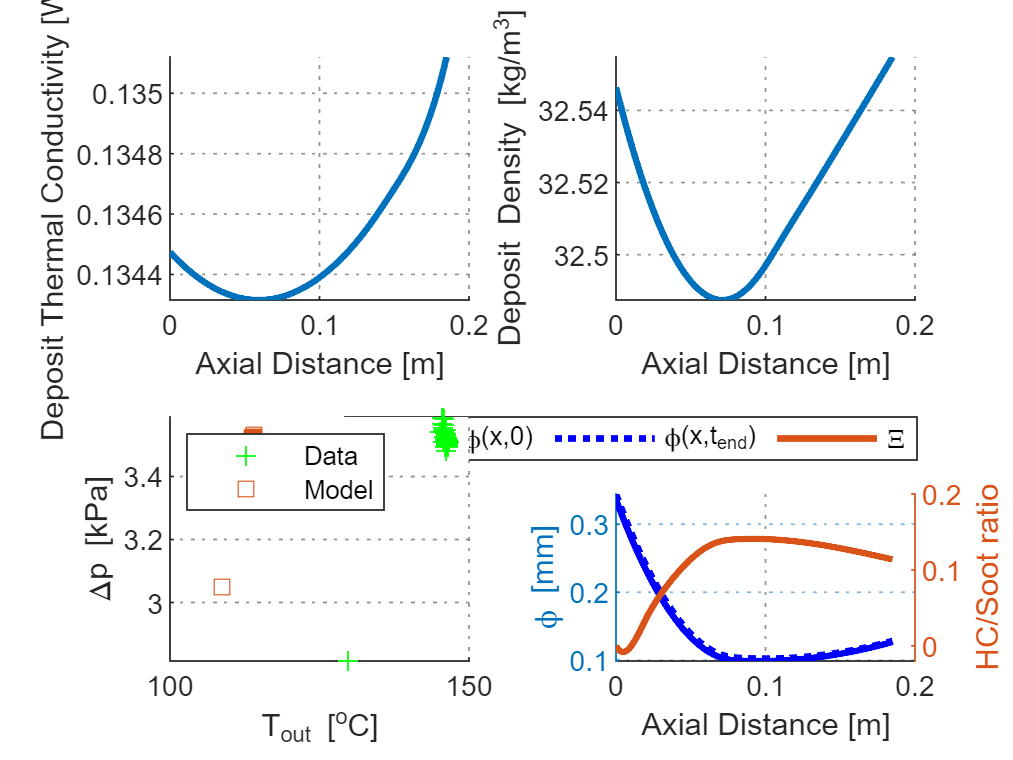

% Plot the best simulation results
E.plotBestSimulation();

## Time Series Plots

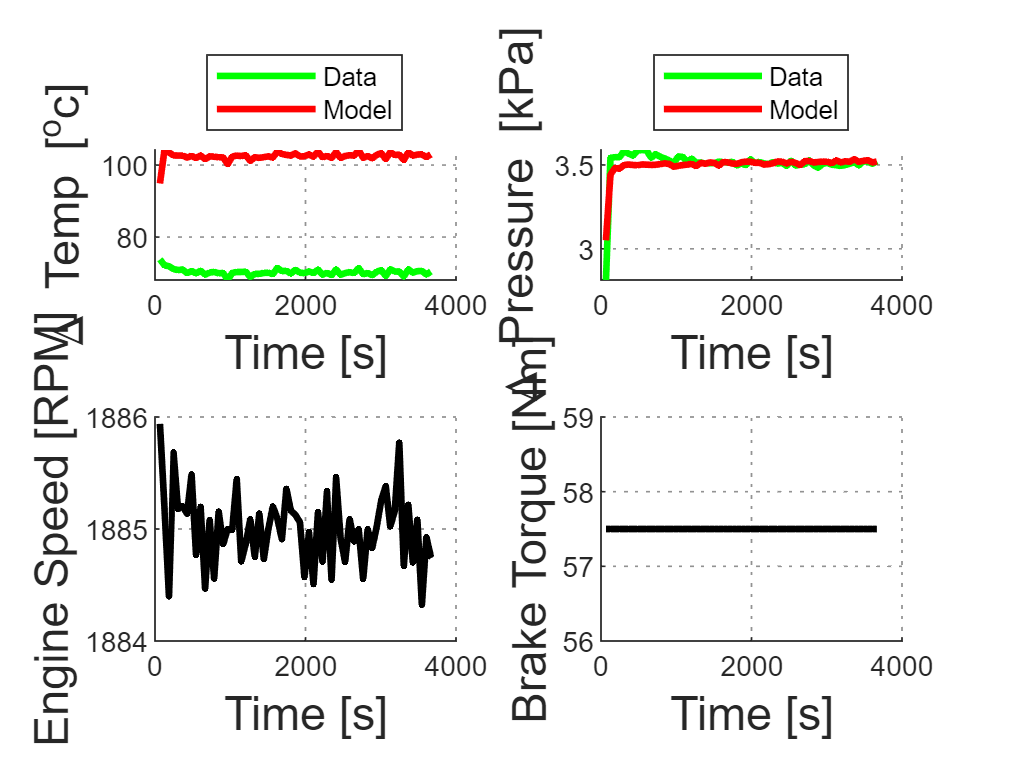

E.plotTimeSeries();

## Output Simulation Parameters to the Workspace

[ FMbest, ModelPara, BoundCond, Options ] = E.exportParameters();